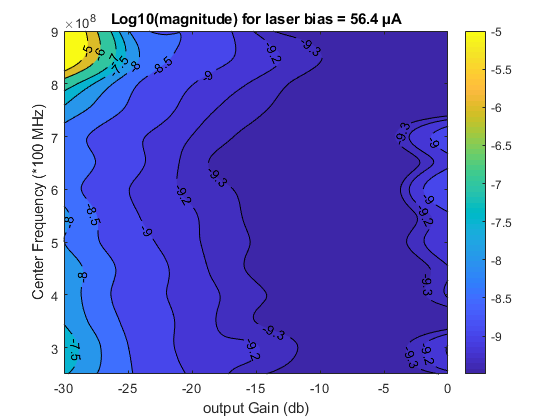

%courant bias%
courant_bias = 56.4; %(µA)%

minGain = -30; %minimum transmited power gain (in db)
maxGain =  0; %maximum transmited power gain (in db)
padGain = 5;   %measure pad for gains
numMeasurmentsGain = (abs(minGain) - abs(maxGain))/padGain;

minCarrierFrequency =  2.5e8; %minimum center frequency supported by adalm pluto (in hz)
maxCarrierFrequency =  9e8; %maximum centr frequency supported by the laser (in hz)
padCarrierFrequency =  50000e3; %pad of 10 khZ
numMeasurementsFreq = (maxCarrierFrequency-minCarrierFrequency)/padCarrierFrequency;
AverageError_function_Gain_CarrierFrequency = zeros(numMeasurementsFreq,numMeasurmentsGain);
Ber_function_Gain_CarrierFrequency = zeros(numMeasurementsFreq,numMeasurmentsGain);

x = minGain : padGain : maxGain;
y = minCarrierFrequency : padCarrierFrequency : maxCarrierFrequency;

% 0.7071 - 0.7071i
data_EVR_qpsk = [0.180815986875508,0.143168475969756,0.124679053518621,0.118232019013970,0.114916043955373,0.114459252954741,0.118286217684172;
    0.194015720101915,0.141528045051375,0.122721864384618,0.120444044163894,0.116177058119325,0.115037156270097,0.126332573768313;
    0.176416965669298,0.137781596863556,0.123121039844939,0.117411462183781,0.115452471970026,0.113996402524346,0.114738692261899;
    0.171995217334774,0.134255059496050,0.122907322125870,0.118032643825894,0.115678041921059,0.114263101633500,0.120711841356308;
    0.171631821721937,0.136416297581255,0.122174570539206,0.116877534844467,0.115165992743074,0.113923444528127,0.119937383979997;
    0.158629993605733,0.131725311196995,0.121060694310456,0.117250476670167,0.115598837448660,0.115166781306397,0.125381570946877;
    0.163135914020711,0.128647437572709,0.120717118237854,0.116848221118805,0.115041077936026,0.113631796523847,0.124325345696256;
    0.149503861182988,0.126165188148031,0.119299700044450,0.116837975411991,0.115131310675211,0.113725570287761,0.139926947817732;
    0.156457702064162,0.130114540785980,0.118736914545250,0.116208430072934,0.114934618215186,0.113125872932836,0.123799651904508;
    0.151016488246326,0.129305233482827,0.120126947085951,0.116541197788785,0.114208950895782,0.115848352488561,0.131910372560842;
    0.172338373513314,0.139126999478983,0.122788115538125,0.118066102655610,0.115401302411536,0.114167349354909,0.114690402783433;
    0.222282984084532,0.146950601931327,0.126234490607302,0.119585809266036,0.115999894732414,0.113941849837816,0.115919322365964;
    0.463899986035227,0.173373546720361,0.135301004723066,0.122962031734888,0.117598344473932,0.115773531131192,0.114461665941270;
    0.536637924330116,0.159560079607009,0.139626957316541,0.119643276852579,0.115738085022843,0.114643192917204,0.113146202953384];

data_ber_qpsk = [0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0,0,0,0,0,0,0;
    0.00115384620000000,8.24176000000000e-05,0,0,0,0,0;
    0.00958791210000000,0,0,0,0,0,0;
    0.00791208790000000,0,0,0,0,0,0];


figure (1)
z1 = 10*log10(data_EVR_qpsk);
%z1(isinf(-z1)) = -5.1;
[Xq,Yq] = ndgrid(minGain:(padGain/10):maxGain,...
    minCarrierFrequency:(padCarrierFrequency/10):maxCarrierFrequency);
% Vq = F(Xq,Yq);
Vq = interp2(x,y,z1,Xq,Yq,'cubic');
contourf(Xq,Yq,Vq,[-11 -9.5 -9.3 -9.2 -9 -8.5 -8 -7.5 -7 -6 -5 0 ],'ShowText','on');
colorbar 
title('Log10(magnitude) for laser bias = 56.4 µA');
xlabel('output Gain (db)');
ylabel('Center Frequency (*100 MHz)');

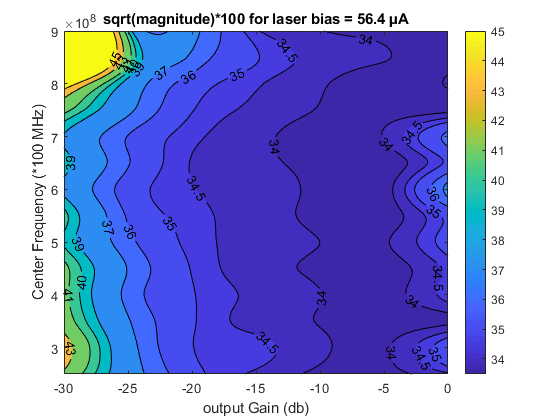


figure (2)
z2 = sqrt(data_EVR_qpsk)*100;
%z1(isinf(-z1)) = -5.1;
[Xq,Yq] = ndgrid(minGain:(padGain/10):maxGain,...
    minCarrierFrequency:(padCarrierFrequency/10):maxCarrierFrequency);
% Vq = F(Xq,Yq);
Vq = interp2(x,y,z2,Xq,Yq,'cubic');
contourf(Xq,Yq,Vq,[45 43 41 40 39 37 36 35 34.5 34 33 32 31 30],'ShowText','on');
colorbar 
title('sqrt(magnitude)*100 for laser bias = 56.4 µA');
xlabel('output Gain (db)');
ylabel('Center Frequency (*100 MHz)');